% Black-Litterman ESG Integration Framework (Long-Only, Percent Returns)
% Course: Bayesian Methods in Finance (IIT Kanpur) Reference: Topic 7 Lecture Slides – Mohammad Arshad Rahman
% Key design choices aligned with lecture notes: 1. Returns: simple percent returns r_t = (P_t - P_{t-1}) / P_{t-1} 2. P (pick matrix): single ESG relative view built from z-scores. Positive z = high ESG risk = short; Negative z = low ESG risk = long. Since z-scores are standardised (mean = 0), sum(z_scores) = 0, so -z_scores forms a valid relative view (elements sum to 0). [Slides pp.16-18: relative view rows sum to zero] 3. Q (view return): Q = P * hist_mean' [Slide eq.(5): Q ~ N(P*mu, Omega); hist_mean is our estimate of mu, the true expected return vector] 4. tau = 1/T [Slide p.23: principled choice reflecting estimation uncertainty in Pi given T observations] 5. Omega = P * (tau*Sigma) * P' [Slide p.19: view uncertainty proportional to variance of the view portfolio] 6. Both BL and Markowitz portfolios solved via long-only QP (quadprog): min (A/2)*w'*Sigma*w - mu'*w s.t. sum(w)=1, w>=0 7. Backtest (Section 13) and Performance Metrics (Section 14).
clear; clc;

% =========================================================
% 1. Data Preparation
% =========================================================
% Load ESG dataset
esg_table = readtable('selected_esg_data.csv')

esg_table = 15×15 table
     Symbol                           Name                                                          Address                                            Sector                              Industry                      FullTimeEmployees                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                


% Keep only rows with valid ESG scores
esg_table = esg_table(~isnan(esg_table.TotalESGRiskScore), :);

% Take first 15 assets for stability
esg_subset = esg_table(1:15, :);
tickers     = esg_subset.Symbol;
esg_scores  = esg_subset.TotalESGRiskScore;  % N x 1
e_scores    = esg_subset.EnvironmentRiskScore;
g_scores    = esg_subset.GovernanceRiskScore;
s_scores    = esg_subset.SocialRiskScore;

% Load historical prices  (rows = days, cols = [date, asset1 ... assetN])
prices = readmatrix('historical_prices.csv')

prices =        NaN  354.4217   97.7794  116.5000   81.7899   39.3088   53.7145   15.5996  190.0840   26.5909  103.6795   55.6151   93.7360   95.9625  142.3536  155.7356
       NaN  356.1401   99.3440  116.5500   84.1546   39.9334   54.0284   16.0730  188.4976   26.8421  106.8703   55.0730   93.6231   95.9716  144.8167  156.8209
       NaN  359.4368  101.6993  120.5500   88.8671   40.1969   56.3130   16.6861  190.0840   26.9799  107.5105   56.2927   97.5723   96.4976  148.9434  159.1247
       NaN  357.8678  104.5850  122.2100   89.2820   41.1978   55.1968   16.7172  191.5303   27.2392  106.4436   55.1916  102.0010   95.7630  148.0604  158.9819
       NaN  363.1351  104.9225  123.8900   87.7222   39.0002   54.6562   16.5309  190.0280   27.0528  105.7453   55.6998  100.9667   97.1687  147.7351  160.0386
       NaN  364.7321  105.6903  123.1200   88.9169   38.8045   53.3482   16.6939  185.9128   26.8259  104.7754   54.5478   99.6879   97.6402  147.7816  161.2571
       NaN  360.0252  107

prices = prices(:, 2:end);   % drop date column  =>  T x N

% =========================================================
% 2. Compute Historical Parameters (Simple Percent Returns)
% r_t = (P_t - P_{t-1}) / P_{t-1}
% =========================================================
returns  = diff(prices) ./ prices(1:end-1, :);   % (T-1) x N
T_train  = size(returns, 1);                      % number of daily obs
N        = length(tickers);                       % number of assets

% Annualised covariance matrix  (252 trading days)
Sigma = cov(returns) * 252;   % N x N

% Annualised historical mean return vector.
% This is our estimate of mu in the BL view equation Q = P*mu.
hist_mean = mean(returns) * 252   % 1 x N  (row vector)

hist_mean =     0.0841    0.1878    0.0353    0.0483    0.0927    0.1937    0.2693    0.1008    0.1039    0.0498    0.0313    0.0954    0.1083   -0.0271    0.1047



% Dimension check
[r, c] = size(Sigma);
if r ~= N || c ~= N
    error('Dimension mismatch: Sigma is %dx%d but N = %d.', r, c, N);
end

fprintf('Returns type : simple percent returns\n');

Returns type : simple percent returns


fprintf('Assets       : %d\n', N);

Assets       : 15


fprintf('Observations : %d daily returns (training)\n', T_train);

Observations : 752 daily returns (training)



% =========================================================
% 3. Establish the Prior – Market Equilibrium [Slide eq.(2)]
% Pi = delta * Sigma * w_mkt
% =========================================================
% Equal-weight market portfolio  (N x 1)
% w_mkt = ones(N, 1) / N;

market_caps = readtable('market_caps.csv')

market_caps = 15×2 table
     Symbol     MarketCap 
    ________    __________

    {'DPZ' }    1.2378e+10
    {'DRI' }    2.2991e+10
    {'DVA' }    9.6644e+09
    {'EMN' }     8.319e+09
    {'WDC' }    1.2479e+11
    {'WELL'}    1.4889e+11
    {'WMB' }    8.6529e+10
    {'WTW' }    2.7622e+10
    {'WY'  }    1.7456e+10
    {'WYNN'}    1.1142e+10
    {'XEL' }     4.909e+10
    {'XYL' }    3.0439e+10
    {'YUM' }    4.4765e+10
    {'ZBH' }     1.843e+10
    {'ZTS' }    5.0976e+10


market_caps = market_caps.MarketCap

market_caps = 1.0e+11 *

    0.1238
    0.2299
    0.0966
    0.0832
    1.2479
    1.4889
    0.8653
    0.2762
    0.1746
    0.1114
    0.4909
    0.3044
    0.4477
    0.1843
    0.5098


w_mkt = market_caps/sum(market_caps)

w_mkt =     0.0187
    0.0347
    0.0146
    0.0125
    0.1881
    0.2244
    0.1304
    0.0416
    0.0263
    0.0168
    0.0740
    0.0459
    0.0675
    0.0278
    0.0768




% Risk-aversion coefficient (delta in eq.(2); same value used as A in eq.(11))
delta = 2.5;

% Equilibrium implied returns  (N x 1)
Pi = delta * Sigma * w_mkt

Pi =     0.0510
    0.0766
    0.0517
    0.1026
    0.1527
    0.0885
    0.0649
    0.0603
    0.0897
    0.1043
    0.0427
    0.0793
    0.0545
    0.0646
    0.0698



fprintf('\nEquilibrium prior Pi computed for %d assets.\n', N);


Equilibrium prior Pi computed for 15 assets.



% =========================================================
% 4. ESG Z-Scores
% =========================================================
% Standardise ESG scores to z-scores  (N x 1)
% Positive z  =>  higher ESG risk  =>  penalised (short in view portfolio)
% Negative z  =>  lower  ESG risk  =>  favoured  (long  in view portfolio)
z_scores = (esg_scores - mean(esg_scores)) / std(esg_scores);

% =========================================================
% 5. Construct ESG View: Pick Matrix P, View Return Q, Uncertainty Omega
% =========================================================
% --- 1. Compute Z-scores for all categories (Relative Views) ---
z_total = (mean(esg_scores) - esg_scores) ./ std(esg_scores);
z_e     = (mean(e_scores)   - e_scores)   ./ std(e_scores);
z_s     = (mean(s_scores)   - s_scores)   ./ std(s_scores);
z_g     = (mean(g_scores)   - g_scores)   ./ std(g_scores);

% Combine into a raw 4 x N matrix
P_rel_raw = [z_total'; z_e'; z_s'; z_g'];

% Row-wise unit-norm normalization for the relative views
row_norms = sqrt(sum(P_rel_raw.^2, 2)); 
P = P_rel_raw ./ row_norms; 


P =    -0.3897   -0.3044   -0.0583   -0.1939    0.5042    0.4138   -0.0181    0.1376    0.2381   -0.2139   -0.2541    0.1677    0.0673   -0.2290    0.1326
   -0.3044   -0.1339    0.3587   -0.4434    0.2703    0.0998   -0.1844    0.3587   -0.2097    0.1503   -0.4371    0.0935    0.0808    0.1377    0.1630
   -0.2009   -0.3931   -0.3313    0.2384    0.3689    0.3963   -0.0568    0.1011    0.3483   -0.1735   -0.0018    0.0394   -0.1460   -0.3588    0.1698
    0.0095    0.1961   -0.2209   -0.0234    0.0315    0.0973    0.3717   -0.4843    0.3168   -0.4624    0.2070    0.1302    0.2509   -0.1661   -0.2539


% --- 4. Scale parameter tau = 1/T [Slide p.23] ---
tau = 1/T_train

tau = 0.0013


% --- 5. View return Q (K x 1 vector) ---
% Here, we use the historical mean as the baseline expectation for all views.
Q = P * hist_mean'   % Dimensions: (4 x N) * (N x 1) = 4 x 1

Q =     0.0841
   -0.0256
    0.0579
    0.1356



% IMPORTANT: For an absolute view to actively tilt the portfolio, you usually 
% provide a specific target return. If you expect these two top ESG stocks 
% to achieve specific annualized returns (e.g., 12% and 10%), uncomment and 
% set them here to override the historical mean:
% Q(5) = 0.12; 
% Q(6) = 0.10;

% --- 6. View uncertainty Omega (K x K matrix) ---
% Using the variance of the view portfolios as proportional uncertainty
Omega_full = P * (tau * Sigma) * P'; 

% In standard Black-Litterman literature, Omega is typically constructed as 
% a diagonal matrix to assume the views are independent from one another.
Omega = ((Omega_full))

Omega = 1.0e-03 *

    0.0931    0.0247    0.0869    0.0204
    0.0247    0.0739   -0.0122   -0.0560
    0.0869   -0.0122    0.1118    0.0315
    0.0204   -0.0560    0.0315    0.0923



% =========================================================
% 6. Bayesian Updating – BL Posterior [Slide eqs.(6),(7)]
% 
% V = [ (tau*Sigma)^{-1} + P'*Omega^{-1}*P ]^{-1}
% mu_BL = V * [ (tau*Sigma)^{-1}*Pi + P'*Omega^{-1}*Q ]
% 
% Dimensions with K=1:
% tauSigma_inv : N x N
% P' (col vector) : N x 1
% Omega_inv : scalar (1x1)
% P'*Omega_inv*P : N x N (rank-1 update via outer product)
% P'*Omega_inv*Q : N x 1
% V : N x N
% mu_BL : N x 1
% =========================================================
tauSigma_inv = inv(tau * Sigma);   % N x N
Omega_inv    = inv(Omega);          

% Posterior covariance  [Slide eq.(7)]
V = inv(tauSigma_inv + P' * Omega_inv * P);   % N x N

% Posterior mean  [Slide eq.(6)]
mu_BL = V * (tauSigma_inv * Pi + P' * Omega_inv * Q);   % N x 1

% =========================================================
% 7. Display Posterior vs Prior
% =========================================================
fprintf('\n--- Black-Litterman Posterior Expected Returns ---\n');


--- Black-Litterman Posterior Expected Returns ---


fprintf('%-10s | %-14s | %-12s | %-12s | %-10s\n', ...
        'Ticker', 'Posterior (BL)', 'Prior (Pi)', 'Hist Mean', 'ESG Z-Score');

Ticker     | Posterior (BL) | Prior (Pi)   | Hist Mean    | ESG Z-Score


fprintf('%s\n', repmat('-', 1, 70));

----------------------------------------------------------------------


for i = 1:N
    fprintf('%-10s | %12.4f   | %10.4f   | %10.4f   | %10.2f\n', ...
            tickers{i}, mu_BL(i), Pi(i), hist_mean(i), z_scores(i));
end

DPZ        |       0.0393   |     0.0510   |     0.0841   |       1.46
DRI        |       0.0759   |     0.0766   |     0.1878   |       1.14
DVA        |       0.0494   |     0.0517   |     0.0353   |       0.22
EMN        |       0.0684   |     0.1026   |     0.0483   |       0.73
WDC        |       0.1279   |     0.1527   |     0.0927   |      -1.89
WELL       |       0.0920   |     0.0885   |     0.1937   |      -1.55
WMB        |       0.0704   |     0.0649   |     0.2693   |       0.07
WTW        |       0.0310   |     0.0603   |     0.1008   |      -0.51
WY         |       0.0842   |     0.0897   |     0.1039   |      -0.89
WYNN       |       0.0011   |     0.1043   |     0.0498   |       0.80
XEL        |       0.0466   |     0.0427   |     0.0313   |       0.95
XYL        |       0.0722   |     0.0793   |     0.0954   |      -0.63
YUM        |       0.0566   |     0.0545   |     0.1083   |      -0.25
ZBH        |       0.0531   |     0.0646   |    -0.0271   |       0.86
ZTS   


% =========================================================
% 8. Predictive Distribution [Slide eq.(10)]
% 
% mu_pred = mu_BL (posterior mean)
% Sigma_pred = Sigma + V (adds estimation uncertainty)
% =========================================================
mu_pred    = mu_BL;       % N x 1
Sigma_pred = Sigma + V;   % N x N

fprintf('\nPredictive distribution computed  (mu_pred = mu_BL, Sigma_pred = Sigma+V).\n');


Predictive distribution computed  (mu_pred = mu_BL, Sigma_pred = Sigma+V).



% =========================================================
% 9. Long-Only BL Portfolio via Quadratic Programming [Slide eq.(11)]
% 
% Constrained QP:
% min (A/2)*w'*Sigma_pred*w - mu_pred'*w
% s.t. ones'*w = 1, w >= 0
% 
% quadprog form: min (1/2)*w'*H*w + f'*w
% H = A * Sigma_pred, f = -mu_pred
% =========================================================
A = 2.5;   % risk-aversion coefficient  [Slide p.28]

% Shared constraints
Aeq     = ones(1, N);
beq     = 1;
lb      = zeros(N, 1);
ub      = [];
qp_opts = optimoptions('quadprog', 'Display', 'off');

% ---- BL long-only QP ----
H_bl = A * Sigma_pred;
f_bl = -mu_pred;

w_BL_long = quadprog(H_bl, f_bl, [], [], Aeq, beq, lb, ub, [], qp_opts);


if isempty(w_BL_long)
    warning('quadprog failed for BL; using clipped fallback.');
    w_raw     = (1/A) * (Sigma_pred \ mu_pred);
    w_raw     = max(w_raw, 0);
    w_BL_long = w_raw / sum(w_raw);
end

% =========================================================
% 10. Long-Only Markowitz (MVO) Portfolio via Quadratic Programming
% 
% min (A/2)*w'*Sigma*w - hist_mean'*w s.t. ones'*w=1, w>=0
% =========================================================
H_mvo = A * Sigma;
f_mvo = -hist_mean';   % hist_mean is 1xN; transpose to Nx1

w_MVO_long = quadprog(H_mvo, f_mvo, [], [], Aeq, beq, lb, ub, [], qp_opts);

if isempty(w_MVO_long)
    warning('quadprog failed for MVO; using clipped fallback.');
    w_raw      = (1/A) * (Sigma \ hist_mean');
    w_raw      = max(w_raw, 0);
    w_MVO_long = w_raw / sum(w_raw);
end

% =========================================================
% 11. Portfolio Weight Comparison Table
% =========================================================
fprintf('\n--- Portfolio Weight Allocation (Long-Only) ---\n');


--- Portfolio Weight Allocation (Long-Only) ---


fprintf('%-10s | %-14s | %-18s | %-16s\n', ...
        'Ticker', 'Market (1/N)', 'MVO Long-Only', 'BL Long-Only');

Ticker     | Market (1/N)   | MVO Long-Only      | BL Long-Only    


fprintf('%s\n', repmat('-', 1, 68));

--------------------------------------------------------------------


for i = 1:N
    fprintf('%-10s | %12.4f   | %16.4f   | %14.4f\n', ...
            tickers{i}, w_mkt(i), w_MVO_long(i), w_BL_long(i));
end

DPZ        |       0.0187   |           0.0000   |         0.0000
DRI        |       0.0347   |           0.0457   |         0.0642
DVA        |       0.0146   |           0.0000   |         0.0191
EMN        |       0.0125   |           0.0000   |         0.0000
WDC        |       0.1881   |           0.0000   |         0.1389
WELL       |       0.2244   |           0.0238   |         0.2645
WMB        |       0.1304   |           0.9306   |         0.2031
WTW        |       0.0416   |           0.0000   |         0.0000
WY         |       0.0263   |           0.0000   |         0.0129
WYNN       |       0.0168   |           0.0000   |         0.0000
XEL        |       0.0740   |           0.0000   |         0.1059
XYL        |       0.0459   |           0.0000   |         0.0252
YUM        |       0.0675   |           0.0000   |         0.1662
ZBH        |       0.0278   |           0.0000   |         0.0000
ZTS        |       0.0768   |           0.0000   |         0.0000



fprintf('\nWeight sums  =>  Market: %.4f | MVO: %.4f | BL: %.4f\n', ...
        sum(w_mkt), sum(w_MVO_long), sum(w_BL_long));


Weight sums  =>  Market: 1.0000 | MVO: 1.0000 | BL: 1.0000


fprintf('Min weights  =>  Market: %.4f | MVO: %.4f | BL: %.4f\n', ...
        min(w_mkt), min(w_MVO_long), min(w_BL_long));

Min weights  =>  Market: 0.0125 | MVO: 0.0000 | BL: 0.0000


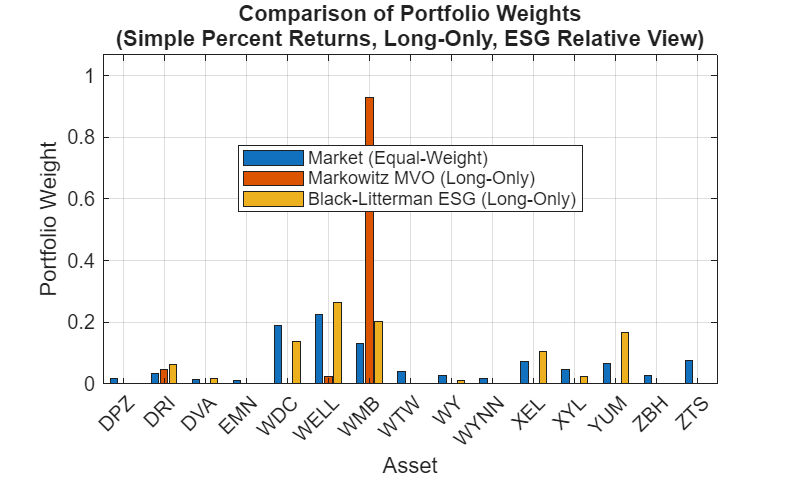


% =========================================================
% 12. Bar Chart: Portfolio Weight Comparison
% =========================================================
figure;
bar([w_mkt, w_MVO_long, w_BL_long]);
set(gca, 'XTickLabel', tickers, 'XTick', 1:N, 'XTickLabelRotation', 45);
legend({'Market (Equal-Weight)', 'Markowitz MVO (Long-Only)', ...
        'Black-Litterman ESG (Long-Only)'}, 'Location', 'best');
title({'Comparison of Portfolio Weights', ...
       '(Simple Percent Returns, Long-Only, ESG Relative View)'});
ylabel('Portfolio Weight');
xlabel('Asset');
grid on;
ylim([0, max([w_mkt; w_MVO_long; w_BL_long]) * 1.15]);


fprintf('\nWeight comparison figure generated.\n');


Weight comparison figure generated.


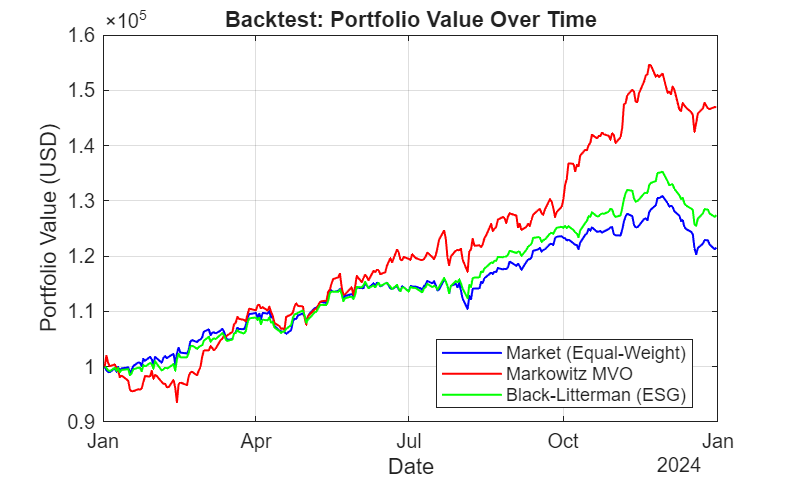


% =========================================================
% 13. Backtest: Portfolio Performance on Out-of-Sample Test Data
% =========================================================
% --- Load test data ---
test_data   = readtable('test_data.csv');
test_dates  = test_data{:, 1};
test_prices = test_data{:, 2:end};      % T_test x N price matrix

% --- Daily simple percent returns ---
test_returns = diff(test_prices) ./ test_prices(1:end-1, :);   % (T_test-1) x N

% --- Normalise weights (all long-only => sum(abs(w)) = 1 already,
%     but kept explicit for robustness) ---
w_mkt_n = w_mkt      / sum(abs(w_mkt));
w_mvo_n = w_MVO_long / sum(abs(w_MVO_long));
w_bl_n  = w_BL_long  / sum(abs(w_BL_long));

% --- Initial portfolio value ---
P0 = 100000;   % USD 100,000

% --- Dollar allocations ---
alloc_mkt = P0 * w_mkt_n;
alloc_mvo = P0 * w_mvo_n;
alloc_bl  = P0 * w_bl_n;

% --- Daily P&L ---
pnl_mkt = test_returns * alloc_mkt;   % (T_test-1) x 1
pnl_mvo = test_returns * alloc_mvo;
pnl_bl  = test_returns * alloc_bl;

% --- Cumulative portfolio value ---
val_mkt = P0 + [0; cumsum(pnl_mkt)];
val_mvo = P0 + [0; cumsum(pnl_mvo)];
val_bl  = P0 + [0; cumsum(pnl_bl)];

% --- Date axis ---
if isdatetime(test_dates)
    plot_dates = test_dates;
else
    plot_dates = datetime(test_dates, 'InputFormat', 'yyyy-MM-dd');
end

% --- Plot cumulative portfolio value ---
figure;
plot(plot_dates, val_mkt, 'b-',  'LineWidth', 1); hold on;
plot(plot_dates, val_mvo, 'r-', 'LineWidth', 1);
plot(plot_dates, val_bl,  'g-',  'LineWidth', 1);
hold off;
legend('Market (Equal-Weight)', 'Markowitz MVO', ...
       'Black-Litterman (ESG)', 'Location', 'Best');
title('Backtest: Portfolio Value Over Time');
xlabel('Date');
ylabel('Portfolio Value (USD)');
grid on;


% =========================================================
% 14. Performance Metrics
% =========================================================
T_test = size(test_returns, 1);
rf     = 0;   % daily risk-free rate (set to 0; replace with actual if needed)

% --- Daily portfolio returns from P&L ---
ret_mkt = pnl_mkt ./ val_mkt(1:end-1);
ret_mvo = pnl_mvo ./ val_mvo(1:end-1);
ret_bl  = pnl_bl  ./ val_bl(1:end-1);

strat_labels  = {'Market', 'Markowitz MVO', 'BL (ESG)'};
strat_returns = {ret_mkt, ret_mvo, ret_bl};
strat_values  = {val_mkt, val_mvo, val_bl};

% =========================================================
% 14. Performance Metrics (Calculated then Printed)
% =========================================================
num_strats = length(strat_labels); % dynamically get number of strategies (3)

% --- 1. Preallocate arrays to store metrics ---
ann_rets   = zeros(num_strats, 1);
ann_vols   = zeros(num_strats, 1);
sharpes    = zeros(num_strats, 1);
max_dds    = zeros(num_strats, 1);
final_vals = zeros(num_strats, 1);

% --- 2. Calculation Loop ---
for i = 1:num_strats
    r   = strat_returns{i};
    val = strat_values{i};

    ann_rets(i)   = prod(1 + r)^(252 / T_test) - 1;
    ann_vols(i)   = std(r) * sqrt(252);
    sharpes(i)    = (ann_rets(i) - rf) / ann_vols(i);
    max_dds(i)    = maxdrawdown(val);   % requires Financial Toolbox
    final_vals(i) = val(end);
end

% --- 3. Print Header ---
fprintf('\n%-25s | %10s  %10s  %10s  %12s  %12s\n', ...
        'Strategy', 'Ann.Return', 'Ann.Vol', 'Sharpe', 'Max DD', 'Final Value');


Strategy                  | Ann.Return     Ann.Vol      Sharpe        Max DD   Final Value


% fprintf('%s\n', repmat('-', 1, 85));

% --- 4. Print Data Loop ---
for i = 1:num_strats
    fprintf('%-25s | %9.2f%%  %9.2f%%  %10.2f  %11.2f%%  $%11.2f\n', ...
            strat_labels{i}, ann_rets(i)*100, ann_vols(i)*100, sharpes(i), max_dds(i)*100, final_vals(i));
end

Market                    |     21.63%      10.77%        2.01         8.05%  $  121533.93
Markowitz MVO             |     47.15%      15.29%        3.08         8.25%  $  146923.58
BL (ESG)                  |     27.53%      10.00%        2.75         7.21%  $  127404.30
